# Inverted Pendulum NNAC

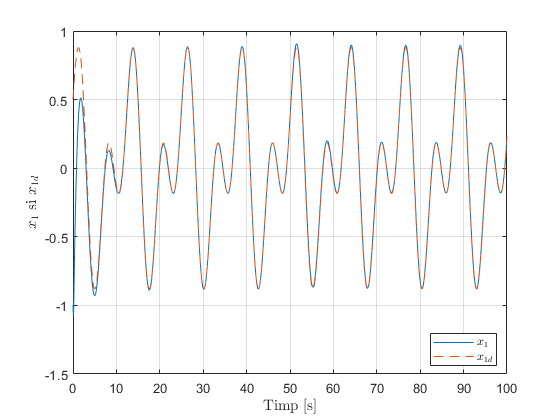

mass = 0.5;
Ac = 0.1*diag([-1 -1]);
x0 = [-1 -0.5]';
lr = 0.5;
gamma = 0.001;

Ts = 0.001;
t = 0:Ts:100;
% desired trajectory
%xd = [ones(1, length(t)); zeros(1, length(t))];
xd = 0.5*[sin(t) + cos(0.5*t); cos(t) - 0.5*sin(0.5*t)];
%xd = [zeros(1, length(t)); zeros(1, length(t))];

m = 20; % number of hidden neurons
n = 4; % number of inputs

% neural network weights
Vc = rands(m, n);
Wc = rands(1, m);

x = zeros(2, length(t));
e = zeros(2, length(t));

x(:, 1) = x0;
u = zeros(length(t), 1);

for i = 1:length(t) - 1
    e(:, i) = x(:, i) - xd(:, i);
    x_cnn = [e(:, i); xd(:, i)];
    
    % backpropagation
    dWc = e(:, i)'/Ac*ones(2, 1)*tanh(Vc*x_cnn)';   
    duda = Wc*(eye(m) - diag(tanh(Vc*x_cnn).^2)); % Wc.*tanh_derivative(Vc*x_cnn)'
    dVc = (e(:, i)'/Ac*ones(2, 1)*duda)'*x_cnn';
    
    Wc = Wc + Ts*(-lr*dWc - gamma*norm(e(:, 1))*Wc);
    Vc = Vc + Ts*(-lr*dVc - gamma*norm(e(:, 1))*Vc);
    
    % inference
    u(i) = -Wc*tanh(Vc*x_cnn);
    
    x(:, i + 1) = x(:, i) + Ts*simplified_pendulum(x(:, i), u(i), mass);% + normrnd(0, 0.00025, [2, 1]);    
  
    if i == 50000
        mass = mass + 0.3;
        %x(1, i + 1) = x(1, i + 1) + 0.3;
    end
end

figure, 
plot(t, x(1, :)); hold on; grid;
plot(t, xd(1, :), "--");
xlabel("Timp [s]", "Interpreter","latex");
ylabel("$x_1$ si $x_{1d}$", "Interpreter","latex");
legend("$x_1$", "$x_{1d}$", "Interpreter", "Latex", "Location","best");

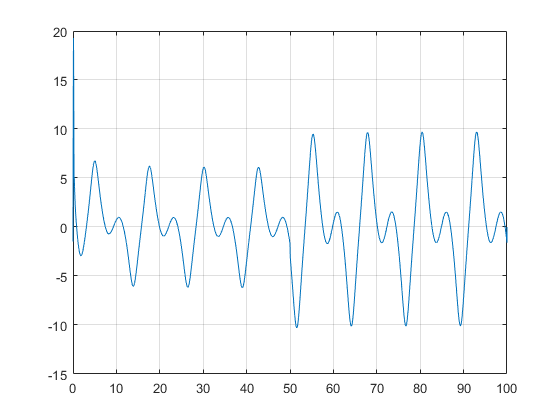


figure, 
plot(t, u); grid;

## Input constrained NNAC

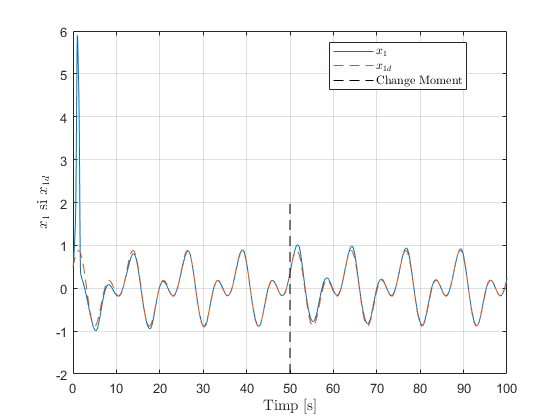

% simulation data
Ts = 0.001;
t = 0:Ts:100;
x0 = [0.5; 0.5];
zeta0 = [0; 0];
mass = 0.5;
input_upperbound = 15;
input_lowerbound = -15;

Ac = -eye(2); 
K = -eye(2);
h = -[-10; -10];

% weight adaption parameters
lr = 0.7; % learining rate
gamma = 0.0001; % damping coefficient

% desired trajectory
xd = 0.5*[sin(t) + cos(0.5*t); cos(t) - 0.5*sin(0.5*t)];

% neural network parameters
input_size = 4;
hidden_layer_size = 20;
Vc = rands(hidden_layer_size, input_size);
Wc = rands(1, hidden_layer_size);

% state and input initialization
x = zeros(2, length(t));
zeta = zeros(2, length(t));
u = zeros(length(t), 1);
e = zeros(2, length(t));

x(:, 1) = x0;
zeta(:, 1) = zeta0;
delta_u = 0;
delta_u_p = 0;

aux = floor(length(t)/2);

for i = 1:length(t) - 1
    if i == aux
        mass = mass + 0.15;
    end
    
    e(:, i) = x(:, i) - xd(:, i) - zeta(:, i);
    x_cnn = [e(:, i); xd(:, i)];
    
    % backpropagation
    dWc = e(:, i)'*(-inv(Ac)*ones(2, 1) + inv(K)*h*delta_u_p)*(-tanh(Vc*x_cnn))';
    dVc = (e(:, i)'*(-inv(Ac)*ones(2, 1) + inv(K)*h*delta_u_p)*(-Wc*diag(1 - tanh(Vc*x_cnn).^2)))'*x_cnn';
    
    Wc = Wc + Ts*(-lr*dWc - gamma*norm(e(:, i))*Wc - gamma*norm(zeta(:, i))*Wc);
    Vc = Vc + Ts*(-lr*dVc - gamma*norm(e(:, i))*Vc - gamma*norm(zeta(:, i))*Vc);
    
    u(i) = -Wc*tanh(Vc*x_cnn);
    [u(i), delta_u] = control_saturation(u(i), input_lowerbound, input_upperbound);
    if delta_u ~= 0
        delta_u_p = 1;
    else
        delta_u_p = 0;
    end
    
    x(:, i + 1) = x(:, i) + Ts*simplified_pendulum(x(:, i), u(i), mass);
    zeta(:, i + 1) = zeta(:, i) + Ts*aux_system_derivative(zeta(:, i), delta_u, K, h);
end

figure, 
plot(t, x(1, :)); hold on; grid;
plot(t, xd(1, :), "--");
plot(t(aux)*ones(length(t), 1), t/25 - 2, "Color", "Black", "LineStyle","--");
xlabel("Timp [s]", "Interpreter","latex");
ylabel("$x_1$ si $x_{1d}$", "Interpreter","latex");
legend("$x_1$", "$x_{1d}$", "Change Moment", "Interpreter", "Latex", "Location","best");

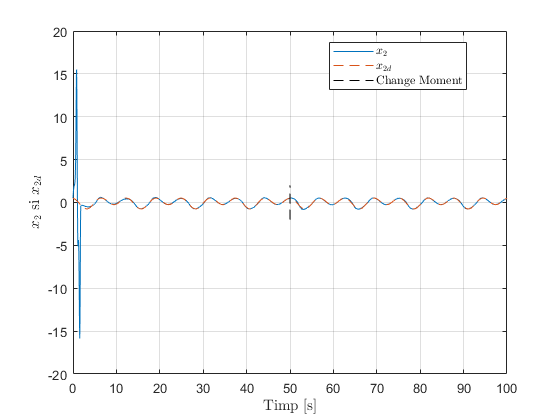


figure, 
plot(t, x(2, :)); hold on; grid;
plot(t, xd(2, :), "--");
plot(t(aux)*ones(length(t), 1), t/25 - 2, "Color", "Black", "LineStyle","--");
xlabel("Timp [s]", "Interpreter","latex");
ylabel("$x_2$ si $x_{2d}$", "Interpreter","latex");
legend("$x_2$", "$x_{2d}$", "Change Moment", "Interpreter", "Latex", "Location","best");

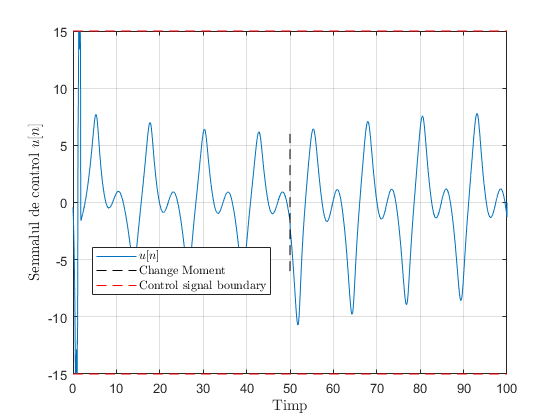


figure,
plot(t, u); grid; hold on;
plot(t(aux)*ones(length(t), 1), t*0.12 - 6, "Color", "Black", "LineStyle","--");
plot(t, input_upperbound*ones(size(t)), "Color", "Red", "LineStyle","--");
plot(t, input_lowerbound*ones(size(t)), "Color", "Red", "LineStyle","--");
xlabel("Timp", "Interpreter","latex");
ylabel("Semnalul de control $u[n]$", "Interpreter","latex");
legend("$u[n]$", "Change Moment", "Control signal boundary",  "Interpreter", "Latex", "Location","best");

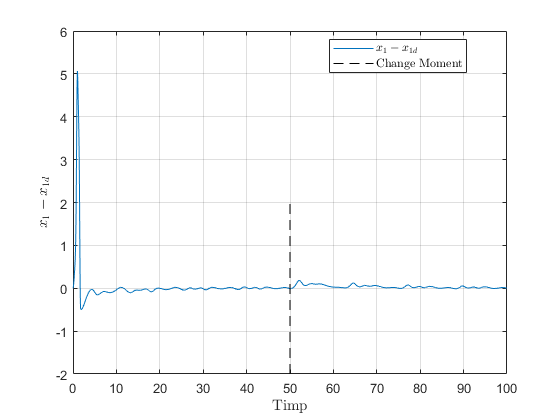


figure, 
plot(t, e(1, :)); grid; hold on;
plot(t(aux)*ones(length(t), 1), t/25 - 2, "Color", "Black", "LineStyle","--");
xlabel("Timp", "Interpreter","latex");
ylabel("$x_1 - x_{1d}$", "Interpreter","latex");
legend("$x_1 - x_{1d}$", "Change Moment", "Interpreter", "Latex", "Location","best");

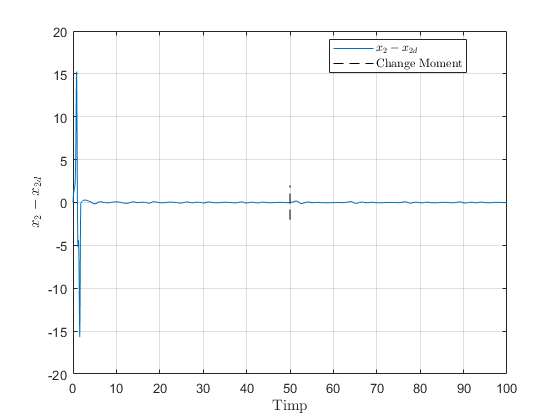


figure, 
plot(t, e(2, :)); grid; hold on;
plot(t(aux)*ones(length(t), 1), t/25 - 2, "Color", "Black", "LineStyle","--");
xlabel("Timp", "Interpreter","latex");
ylabel("$x_2 - x_{2d}$", "Interpreter","latex");
legend("$x_2 - x_{2d}$", "Change Moment", "Interpreter", "Latex", "Location","best");

## Input constrained with NN based observer

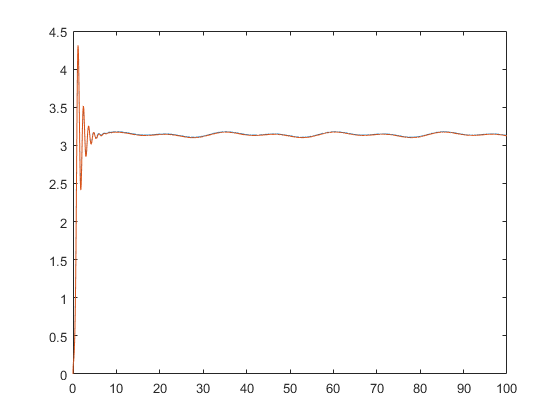

% simulation time initialization
Ts = 0.01;
t = 0:Ts:100;

% desired trajectory
yd = 0.1*[sin(0.5*t) + cos(0.25*t); 0.5*cos(0.5*t) - 0.25*sin(0.25*t)];
%yd = zeros(2, length(t));
%yd = [ones(1, length(t)); zeros(1, length(t))];

% model parameters
mass = 0.5;
x0 = [0.1; 0.2];
Ac = -0.1*eye(2);
C = [1; 0];

% auxiliary system parameters
K = -eye(2);
h = -[10; 10]; % modifica aici DACA NU MERGE!!!!
zeta0 = [0; 0];

% controller neural network parameters
input_size_cnn = 4;
hidden_layer_size_cnn = 20;
lr_c = 0.7;
gamma_c = 0.01;

% observer parameters
A = [0 1; 0 0];
B = [0; 1];
G = [15; 15];
%G = [14;49];
G = [43; 460];
Lambda = 0.6;
x_hat0 = [0; 0];
Obs = [C'; C'*Ac];
Aocl = A - G*C';

% observer neural network parameters
input_size_onn = 3;
hidden_layer_size_onn = 20;
lr_o = 30;
gamma_o = 0.03;

% control signal saturation limits
input_upper_bound = 20;
input_lower_bound = -20;

% controller neural network initialization
Vc = rands(hidden_layer_size_cnn, input_size_cnn);
Wc = rands(1, hidden_layer_size_cnn);
Vo = rands(hidden_layer_size_onn, input_size_onn);
Wo = rands(1, hidden_layer_size_onn);

% model state initialization
x = zeros(2, length(t));
zeta = zeros(2, length(t));
xi_hat = zeros(2, length(t));
x(:, 1) = x0;
zeta(:, 1) = zeta0;

u = zeros(length(t), 1);
e = zeros(2, length(t));
y_e = zeros(length(t), 1);
r = zeros(length(t), 1);

for i = 1:length(t) - 1
    e(:, i) = x(:, i) - yd(:, i) - zeta(:, i);
    y_e(i) = C'*x(:, i) - C'*xi_hat(:, i);
    
    x_onn = [xi_hat(:, i); yd(1, i)];
    
    % backpropagation
    dWo = (y_e(i)*C'*inv(Aocl)*B)'*tanh(Vo*x_onn)';
    dVo = (y_e(i)*C'*inv(Aocl)*B*Wo*(eye(hidden_layer_size_onn) - diag(tanh(Vo*x_onn).^2)))'*x_onn';

    % update
    Wo = Wo + Ts*(-lr_o*dWo - gamma_o*norm(y_e(i))*Wo);
    Vo = Vo + Ts*(-lr_o*dVo - gamma_o*norm(y_e(i))*Vo);
 
    H_hat = Wo*tanh(Vo*x_onn);
    
    x(:, i + 1) = x(:, i)+ Ts*simplified_pendulum(x(:, i), yd(1, i), mass);
    xi_hat(:, i + 1) = xi_hat(:, i) + Ts*observer_derivative(xi_hat(:, i), A, B, C, G, C'*x(:, i), H_hat);
end

figure, 
plot(t, x(1, :)); hold on;
plot(t, xi_hat(1, :));

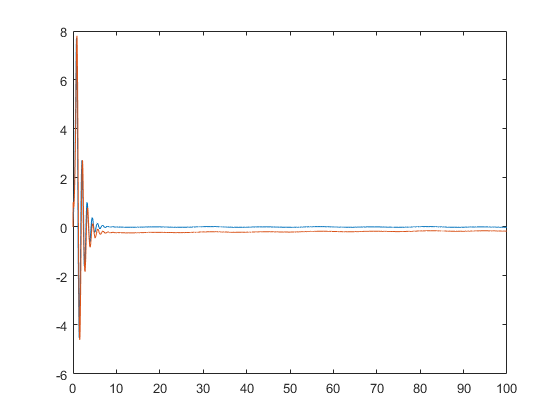


figure,
plot(t, x(2, :)); hold on;
plot(t, xi_hat(2, :));


x_cnn = [x(1, 1) - yd(1, 1); xi_hat(2, 1) - yd(2, 1); yd(:, 1)] - [zeta(:, 1); 0; 0];
[u(1), delta_u] = control_saturation(-Wc*tanh(Vc*x_cnn), input_lower_bound, input_upper_bound);

for i = 1:length(t) - 1
    if i == 1000
        disp('ok');
    end
    e(:, i) = [x(1, i); xi_hat(2, i)] - yd(:, i) - zeta(:, i);
    y_e(i) = C'*x(:, i) - C'*xi_hat(:, i);
    r(i) = [Lambda 1]*e(:, i);
    
    x_onn = [x(1, i); xi_hat(2, i); u(i)];
    x_cnn = [x(1, i) - yd(1, i); xi_hat(2, i) - yd(2, i); yd(:, i)] - [zeta(:, i); 0; 0];
    
    if delta_u ~= 0
        delta_u_p = 1;
    else
        delta_u_p = 0;
    end
    % backpropagation
    dWo = (y_e(i)*C'*inv(Aocl)*B)'*tanh(Vo*x_onn)';
    dVo = (y_e(i)*C'*inv(Aocl)*B*Wo*(eye(hidden_layer_size_onn) - diag(tanh(Vo*x_onn).^2)))'*x_onn';
    dWc = r(i)*[Lambda 1]*(Obs*inv(Ac)*ones(2, 1) - inv(K)*h*delta_u_p)*tanh(Vc*x_cnn)';
    dVc = r(i)*([Lambda 1]*(Obs*inv(Ac)*ones(2, 1) - inv(K)*h*delta_u_p)*Wc*(eye(hidden_layer_size_cnn) - diag(tanh(Vc*x_cnn).^2)))'*x_cnn';
    
    % update
    Wo = Wo + Ts*(-lr_o*dWo - gamma_o*norm(y_e(i))*Wo);
    Vo = Vo + Ts*(-lr_o*dVo - gamma_o*norm(y_e(i))*Vo);
    Wc = Wc + Ts*(-lr_c*dWc - gamma_c*norm(r(i))*Wc - gamma_c*norm(zeta(:, i))*Wc);
    Vc = Vc + Ts*(-lr_c*dVc - gamma_c*norm(r(i))*Vc - gamma_c*norm(zeta(:, i))*Vc);
    
    u(i) = -Wc*tanh(Vc*x_cnn);
    [u(i), delta_u] = control_saturation(u(i), input_lower_bound, input_upper_bound);
    
    H_hat = Wo*tanh(Vo*x_onn);
    
    x(:, i + 1) = x(:, i)+ Ts*simplified_pendulum(x(:, i), u(i), mass);
    zeta(:, i + 1) = zeta(:, i) + Ts*aux_system_derivative(zeta(:, i), delta_u, K, h);
    xi_hat(:, i + 1) = xi_hat(:, i) + Ts*observer_derivative(xi_hat(:, i), A, B, C, G, C'*x(:, i), H_hat);
    
    if i == 50000
        %x(:, i + 1) = x(:, i + 1) + 0.1;
    end
end

ok


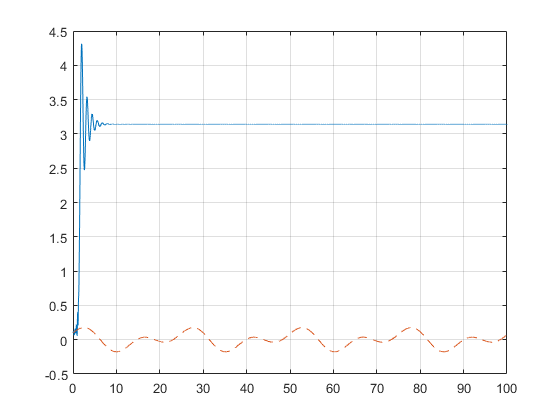


figure, 
plot(t, x(1, :)); grid; hold on;
plot(t, yd(1, :), '--');

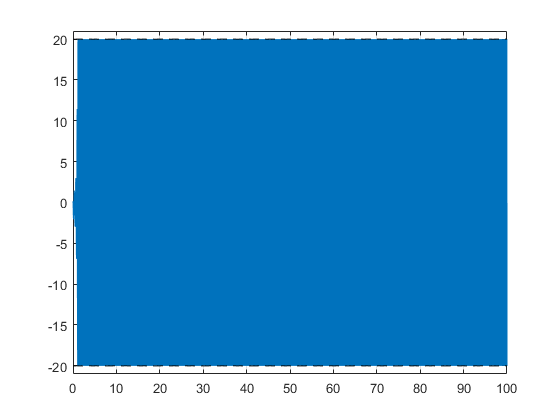


figure, 
plot(t, u); grid; hold on;
plot(t, input_lower_bound*ones(length(t), 1), "Color","Black", "LineStyle","--");
plot(t, input_upper_bound*ones(length(t), 1), "Color","Black", "LineStyle","--");
axis([0 100 input_lower_bound - 1 input_upper_bound + 1])

function dx = simplified_pendulum(x, u, m)
    l = 0.3;
    J = 0.006;
    b = 0.1;
    g = 9.8;
    
    dx = [x(2);
          ((m*g*l)/(J + m*l^2))*sin(x(1)) - (b/(J + m*l^2))*x(2) + (l/(J + m*l^2))*cos(x(1))*u];
end

function dzeta = aux_system_derivative(zeta, delta_u, K, h)
    dzeta = K*zeta + h*delta_u;
end

function [u_saturated, delta_u] = control_saturation(u, lower_bound, upper_bound)
   if u < lower_bound
       u_saturated = lower_bound;
   else 
       if u > upper_bound
           u_saturated = upper_bound;
       else
           u_saturated = u;
       end
   end
   
   delta_u = u - u_saturated;
end

function dxi_hat = observer_derivative(xi_hat, A, B, C, G, y, H_hat)
    dxi_hat = A*xi_hat + B*H_hat + G*(y - C'*xi_hat);
end